K = 2; M = 8;Rc = 100;
% --- Define Network Parameters ---
inputSize = M*K +2;         % Dimension of the input feature vector [l_n; u; v]
outputSize = 370;         % Dimension of the output [Real(g_n), Imag(g_n)]
numResidualBlocks = 5;  % Number of residual blocks (effectively determining hidden depth)
hiddenDim = 500;         % Number of neurons in hidden layers within blocks (tune this)
dropoutProb = 0;      % Dropout probability for regularization (tune this)
l2Reg = 0;           % L2 regularization factor (tune this)
 
valratio = 0.2;
N_elements = 16;

% MLP数据，角度作为输出
dataFolder = 'dataset/dataset_smallarray/';  % 你的数据目录
fileList = dir(fullfile(dataFolder, '*.mat'));

N_sample = 100;
X_set = [];
Y_set = [];

% for i = 1:length(fileList)
%     load(fullfile(dataFolder, fileList(i).name));

for i = 1:50
    filename = sprintf( dataFolder + "G_complex_4.17_%d", i);
    load(filename + ".mat");
    
    points = model_points{1};
    
    ln_all = zeros(K*M + 2, N_elements);
    for j = 1:16
        ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, 20, 15, [Inf,Inf], 22.5, 22.5);
    end
    X_set = [X_set; ln_all(1:2+K*M, :).'];
    Y_set = [Y_set; G_complex_all.'];
end
Y_set = abs(Y_set);

cv = cvpartition(size(X_set, 1), 'HoldOut', 0.2);  

% 获取训练和测试索引
idxTrain = training(cv);
idxTest = test(cv);

% 提取训练集和测试集
XTrain = X_set(idxTrain, : );
YTrain = Y_set(idxTrain, :);

XValidation = X_set(idxTest, :);
YValidation = Y_set(idxTest, :);

% --- 输入参数 ---
N = 100; % 坐标点数量
L = 10;  % 网格边长 (L x L 网格)

% 1. 生成示例坐标数据 (N x 2)
% 假设坐标范围在 x: [0, 10], y: [0, 10]
rng(0); % 为了可复现性
coords = rand(N, 2) * 10; 

% 2. 定义网格的坐标范围
x_min_grid = 0;
x_max_grid = 10;
y_min_grid = 0;
y_max_grid = 10;

% --- 核心逻辑 ---
% 创建网格的边界 (L+1 个边界定义 L 个 bin)
x_edges = linspace(x_min_grid, x_max_grid, L + 1);
y_edges = linspace(y_min_grid, y_max_grid, L + 1);

% 使用 histcounts2 计算每个网格单元中的点数
% H 的行对应 y_edges, 列对应 x_edges
% H(i,j) 是落在 y_edges(i)<=y<y_edges(i+1) 和 x_edges(j)<=x<x_edges(j+1) 范围内的点数
counts_grid = histcounts2(coords(:,1), coords(:,2), x_edges, y_edges);

% 将计数大于0的网格标记为1，其余为0
% 注意：histcounts2 的输出 H(row, col) 对应 Y 在第 row 个 bin, X 在第 col 个 bin。
% MATLAB 中矩阵 (row, col) 通常解释为 (y, x)。
% 如果你希望 grid(1,1) 对应左下角，可能需要 flipud(counts_grid') 或根据需求调整。
% 默认情况下，imagesc(counts_grid) 会将第一行显示在顶部。
binary_grid = double(counts_grid > 0); 

% --- 输出和可视化 (可选) ---
disp('生成的二值化网格:');

生成的二值化网格:


disp(binary_grid);

     0     1     1     0     0     0     1     1     1     1
     0     0     0     1     1     1     1     0     1     1
     1     1     1     1     1     0     0     1     0     0
     0     1     0     1     0     1     1     1     0     1
     1     0     1     0     1     1     0     0     1     1
     1     1     1     1     1     1     1     1     0     1
     1     1     1     0     1     0     1     0     1     1
     1     1     1     1     1     1     1     1     1     0
     1     1     1     0     0     0     0     0     1     0
     1     1     1     1     1     1     1     1     0     1



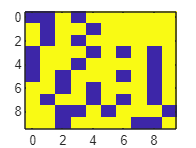


figure;
imagesc(x_edges(1:end-1), y_edges(1:end-1), binary_grid'); % Transpose for typical (x,y) axis

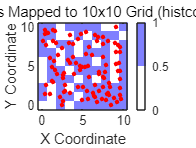

% 或者直接 imagesc(binary_grid) 如果你接受默认的轴对应
% imagesc(binary_grid);
% colormap([1 1 1; 0 0 1]); % 白色为0，蓝色为1
% colorbar;
% axis equal tight;
% set(gca, 'YDir', 'normal'); % 将 (0,0) 置于左下角，Y轴向上
% xlabel('X Grid Index / X Coordinate');
% ylabel('Y Grid Index / Y Coordinate');
% title(sprintf('N=%d Coordinates Mapped to %dx%d Grid', N, L, L));

% 如果想让Y轴像标准绘图一样向上，并且X、Y坐标轴对应：
figure;
imagesc([x_min_grid, x_max_grid], [y_min_grid, y_max_grid], binary_grid');
set(gca, 'YDir', 'normal');
xlabel('X Coordinate');
ylabel('Y Coordinate');
title(sprintf('Coordinates Mapped to %dx%d Grid (histcounts2)', L, L));
hold on;
plot(coords(:,1), coords(:,2), 'r.', 'MarkerSize', 8); % 绘制原始点
hold off;
colormap([1 1 1; 0.5 0.5 1]); % 背景白色，标记浅蓝色
colorbar;


lgraph = layerGraph;
%% ！！全连接网络
% --- Input Layer ---
inputLayers = [
    featureInputLayer(inputSize, 'Name', 'input')
    fullyConnectedLayer(hiddenDim, 'Name', 'fc_initial', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Initial projection
    reluLayer('Name','relu_initial')
    ];
lgraph = addLayers(lgraph, inputLayers);    

% --- Create Residual Blocks ---
currentLayerOutput = 'relu_initial'; % Output name of the initial layers

for i = 1:numResidualBlocks
    blockName = sprintf('resBlock%d', i);

    % Layers within the residual block
    blockLayers = [
        fullyConnectedLayer(hiddenDim, 'Name', [blockName '_fc1'], 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg)
        dropoutLayer(dropoutProb, 'Name', [blockName '_drop1']) % Optional dropout
        batchNormalizationLayer('Name', [blockName '_bn1'])
        reluLayer('Name', [blockName '_relu1'])
    ];
    lgraph = addLayers(lgraph, blockLayers);
    lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_fc1']);
    currentLayerOutput = [blockName '_relu1'];
end

outputLayers = [
    fullyConnectedLayer(outputSize, 'Name', 'fc_output', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Final FC layer to get 2 outputs
    regressionLayer('Name', 'output') % Regression layer for training
    ];
lgraph = addLayers(lgraph, outputLayers);

% Connect the last residual block to the final output layer
lgraph = connectLayers(lgraph, currentLayerOutput, 'fc_output');

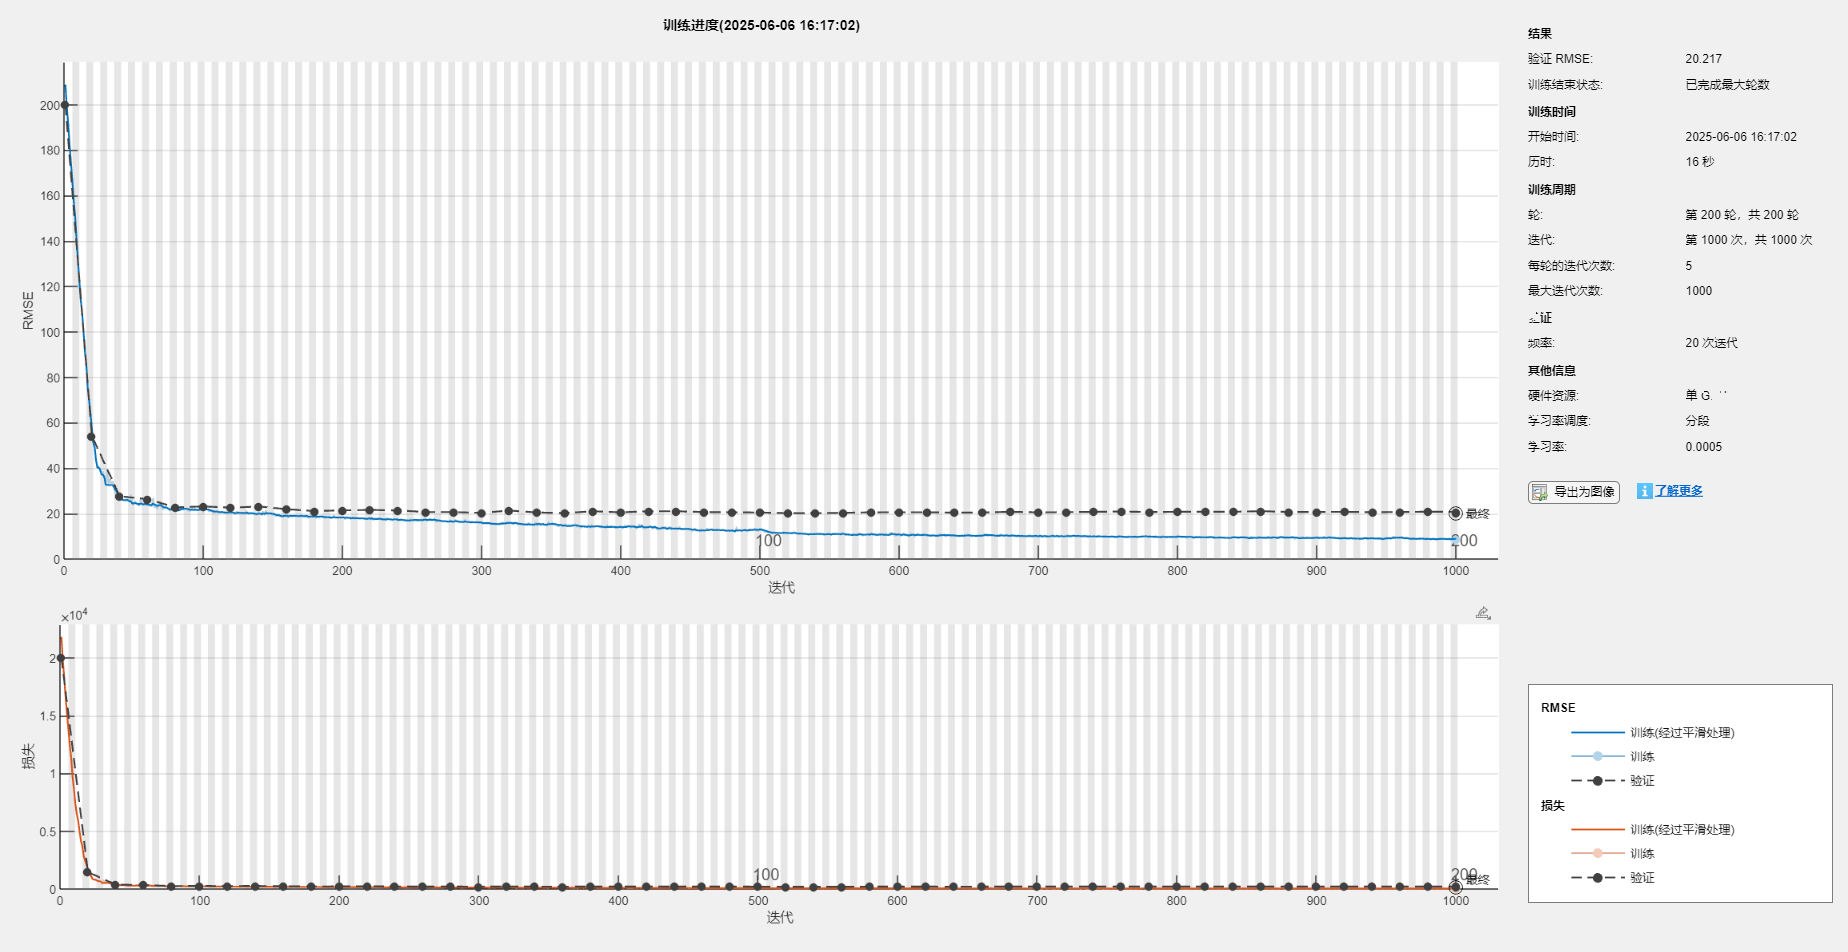

options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...             % May need more epochs for deep networks
    'MiniBatchSize', 128, ...
    'InitialLearnRate', 2.5e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'ValidationPatience', 100,...
    'LearnRateDropFactor', 0.2, ...   % More aggressive drop for deeper nets?
    'LearnRateDropPeriod', 100, ...  % Adjust drop period
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency', 20, ...    % Adjust validation frequency 
    'Shuffle', 'every-epoch', ...
    'Plots','training-progress',...
    'Verbose', false, ...
    'VerboseFrequency', 20, ...
    'ExecutionEnvironment', 'auto'); % Use GPU if available ('gpu')
trainedNet = trainNetwork(XTrain, YTrain, lgraph, options);

% --- Prediction (Example) ---
YPred = predict(trainedNet, XValidation);
YPred_Train = predict(trainedNet, XTrain);

rmse_train = sqrt(mean(sum((YTrain - YPred_Train).^2,2)))   

rmse_train = single
8.1331

rmse_val = sqrt(mean(sum((YValidation - YPred).^2,2)))

rmse_val = single
20.2167

正在将数据插值到 uv 网格...


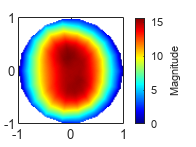

已生成 uv 域插值 pcolor 图。


i = 12;
phi_ = 0:20:180;
theta_ = -90:5:90;

u_ = sind(theta_).' * cosd(phi_);
v_ = sind(theta_).' * sind(phi_);
angles_uv = [u_(:), v_(:)];
% plot_inUV(double(YPred_Train(i,:)), angles_uv);
% plot_inUV(abs(YTrain(i,:)), angles_uv);
plot_inUV(double(YPred(i,:)), angles_uv);

正在将数据插值到 uv 网格...


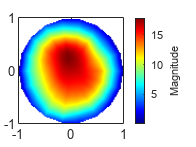

已生成 uv 域插值 pcolor 图。


plot_inUV(abs(YValidation(i,:)), angles_uv);

% % --- Define Network Parameters ---
% inputSize = input_feature_size;         % Dimension of the input feature vector [l_n; u; v]
% outputSize = u_points * v_points;         % Dimension of the output [Real(g_n), Imag(g_n)]
% numResidualBlocks = 10;  % Number of residual blocks (effectively determining hidden depth)
% hiddenDim = 200;         % Number of neurons in hidden layers within blocks (tune this)
% dropoutProb = 0;      % Dropout probability for regularization (tune this)
% l2Reg = 0;           % L2 regularization factor (tune this)

% lgraph = layerGraph;
% 
% % --- Input Layer ---
% inputLayers = [
%     featureInputLayer(inputSize, 'Name', 'input', 'Normalization', 'zscore')
%     fullyConnectedLayer(hiddenDim, 'Name', 'fc_initial', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Initial projection
%     reluLayer('Name','relu_initial')
%     ];
% lgraph = addLayers(lgraph, inputLayers);
% 
% % --- Create Residual Blocks ---
% currentLayerOutput = 'relu_initial'; % Output name of the initial layers
% 
% for i = 1:numResidualBlocks
%     blockName = sprintf('resBlock%d', i);
% 
%     % Layers within the residual block
%     blockLayers = [
%         fullyConnectedLayer(hiddenDim, 'Name', [blockName '_fc1'], 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg)
%         batchNormalizationLayer('Name', [blockName '_bn1'])
%         reluLayer('Name', [blockName '_relu1'])
%         dropoutLayer(dropoutProb, 'Name', [blockName '_drop1']) % Optional dropout
% 
%         fullyConnectedLayer(hiddenDim, 'Name', [blockName '_fc2'], 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg)
%         batchNormalizationLayer('Name', [blockName '_bn2'])
%         % Note: ReLU after addition
%     ];
%     lgraph = addLayers(lgraph, blockLayers);
% 
%     % Addition layer for the skip connection
%     addLayer = additionLayer(2, 'Name', [blockName '_add']); % Add two inputs
%     lgraph = addLayers(lgraph, addLayer);
% 
%     % Final ReLU for the block
%     finalReluLayer = reluLayer('Name', [blockName '_relu_final']);
%     lgraph = addLayers(lgraph, finalReluLayer);
% 
%     % --- Connect Layers within the block and the skip connection ---
%     % Connect main path within the block
%     lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_fc1']); % Input to block's first FC
%     lgraph = connectLayers(lgraph, [blockName '_bn2'], [blockName '_add/in1']); % Main path output to addition layer
% 
%     % Connect skip connection path
%     lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_add/in2']); % Block input to addition layer
% 
%     % Connect addition layer to final ReLU
%     lgraph = connectLayers(lgraph, [blockName '_add'], [blockName '_relu_final']);
% 
%     % Update the output name for the next iteration/block
%     currentLayerOutput = [blockName '_relu_final'];
% end
% 
% outputLayers = [
%     fullyConnectedLayer(outputSize, 'Name', 'fc_output', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Final FC layer to get 2 outputs
%     regressionLayer('Name', 'output') % Regression layer for training
%     ];
% lgraph = addLayers(lgraph, outputLayers);
% 
% % Connect the last residual block to the final output layer
% lgraph = connectLayers(lgraph, currentLayerOutput, 'fc_output');